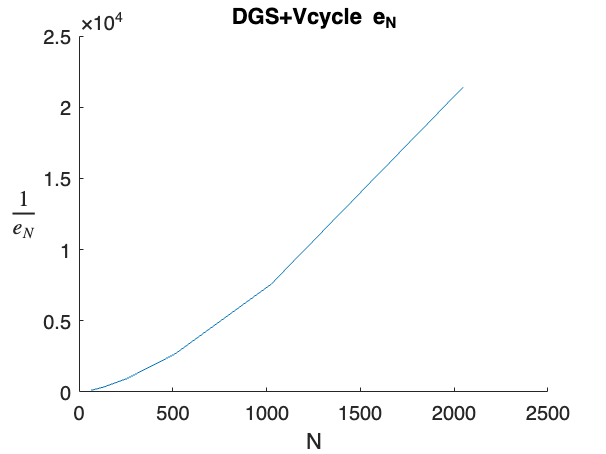

addpath("test_func", "up_down_operator");
Nset = [64; 128; 256; 512; 1024; 2048];
err = zeros(length(Nset), 1);
t = zeros(length(Nset), 1);
stp = zeros(length(Nset), 1);
for i = 1: length(Nset)
    tic;
    N = Nset(i);
    para = get_para(N);
    [poi, stp(i)] = Vcycle_DGS(para);
    err(i) = err_std(poi, para);
    t(i) = toc;
end
figure;
hold on;
plot(Nset, 1./err);
title("DGS+Vcycle e_N");
xlabel("N");
ylabel("$\frac{1}{e_N}$", ...
    'interpreter', 'latex', ...
    "Rotation",0);
hold off;

Names = {'N'; 'time'; 'e_N'; 'steps'};
T = table(Nset, t, err, stp, ...
    'VariableNames',Names)

T = 6×4 table
     N       time         e_N        steps
    ____    _______    __________    _____

      64    0.14275     0.0085233      6  
     128    0.12871     0.0030007      6  
     256    0.57573     0.0010587      7  
     512     2.4236    0.00037395      7  
    1024     18.537    0.00013215      7  
    2048     94.143    4.6709e-05      7  


table2latex(T, 'table.tex')

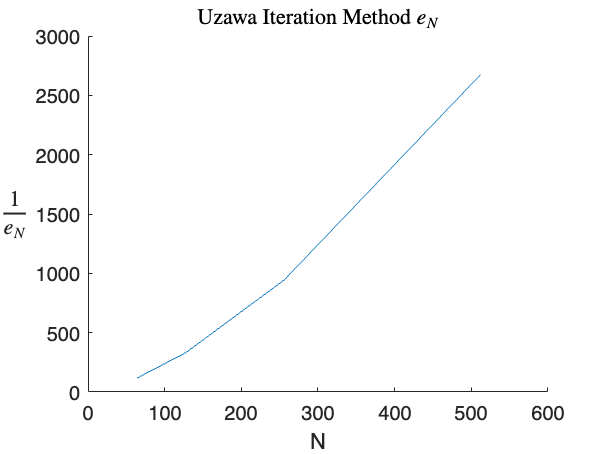

addpath("test_func", "up_down_operator");
Nset = [64; 128; 256; 512];
err = zeros(length(Nset), 1);
t = zeros(length(Nset), 1);
for i = 1: length(Nset)
    tic;
    N = Nset(i);
    para = get_para(N);
    poi = UIM(para);
    err(i) = err_std(poi, para);
    t(i) = toc;
end
figure;
hold on;
plot(Nset, 1./err);
title("Uzawa Iteration Method $e_N$", ...
    'interpreter', 'latex');
xlabel("N");
ylabel("$\frac{1}{e_N}$", ...
    'interpreter', 'latex', ...
    "Rotation",0);
hold off;

Names = {'N'; 'time'; 'e_N'};
T = table(Nset, t, err, ...
    'VariableNames',Names)

T = 4×3 table
     N      time         e_N    
    ___    _______    __________

     64    0.13661     0.0085233
    128    0.47766     0.0030007
    256     4.7065     0.0010587
    512     27.945    0.00037395


table2latex(T, 'table.tex')

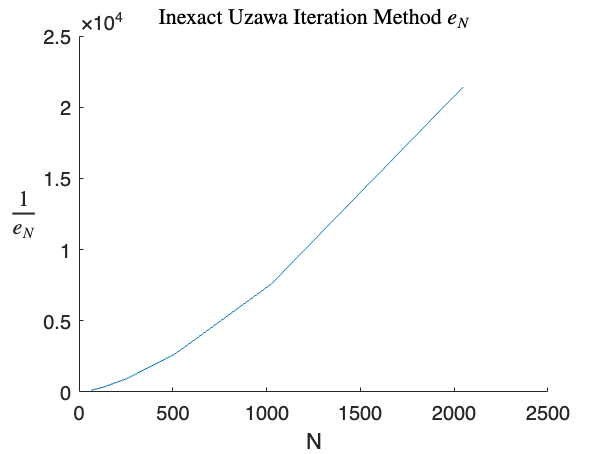

addpath("test_func", "up_down_operator");
Nset = [64; 128; 256; 512; 1024; 2048];
err = zeros(length(Nset), 1);
t = zeros(length(Nset), 1);
stp = zeros(length(Nset), 1);
for i = 1: length(Nset)
    tic;
    N = Nset(i);
    para = get_para(N);
    [poi, stp(i)] = IUIM(para);
    err(i) = err_std(poi, para);
    t(i) = toc;
end
figure;
hold on;
plot(Nset, 1./err);
title("Inexact Uzawa Iteration Method $e_N$", ...
    'interpreter', 'latex');
xlabel("N");
ylabel("$\frac{1}{e_N}$", ...
    'interpreter', 'latex', ...
    "Rotation",0);
hold off;

Names = {'N'; 'time'; 'e_N'; 'steps'};
T = table(Nset, t, err, stp, ...
    'VariableNames',Names)

T = 6×4 table
     N        time         e_N        steps
    ____    ________    __________    _____

      64    0.065143     0.0085233      4  
     128     0.25165     0.0030007      4  
     256     0.99247     0.0010587      4  
     512      4.0304    0.00037395      4  
    1024      24.401    0.00013212      4  
    2048      129.38    4.6674e-05      4  


table2latex(T, 'table.tex')

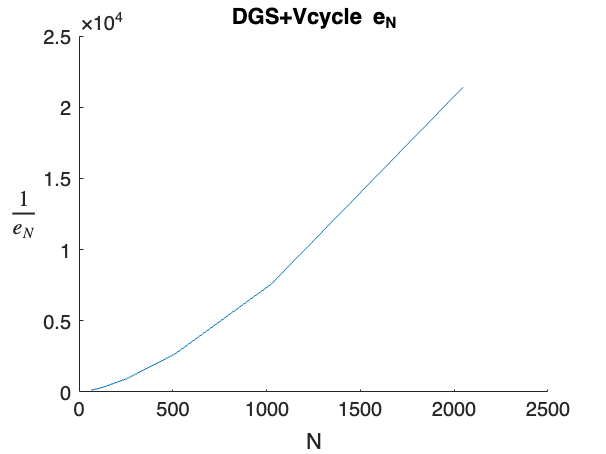

figure;
hold on;
plot(Nset, 1./err);
title("Uzawa Iteration Method e_N");
xlabel("N");
ylabel("$\frac{1}{e_N}$", ...
    'interpreter', 'latex', ...
    "Rotation",0);
hold off;

tic;
N = 2048;
para = get_para(N);
poi = IUIM(para);
err_std(poi, para)
t = toc

table2latex(T, 'table.tex')